% given data
A = [0, 3, 0, 0; -3, 0,  0, 0; 0, 0, 0, 1; 0, 0, -1, 0];
B = [0; 0; 0; 0];
C = [2, 0, 0, 3];
D = 0;
sys = ss(A, B, C, D);
x0 = [1; 1; 1; 1];
x_0 = [2; 0; 0; -1];
eig_A = eig(A)

eig_A =    0.0000 + 3.0000i
   0.0000 - 3.0000i
   0.0000 + 1.0000i
   0.0000 - 1.0000i



% Finding the matrix L by given spectrum of matrix (A+LC)
G = [-1, 0, 0, 0; 
    0, -10, 0, 0; 
    0, 0, -3, 4; 
    0, 0, -4, -3];

Y = [1; 1; 1; 1];

% Solving Sylvester's equations
cvx_begin sdp
variable Q(4, 4)
G*Q - Q*A == Y*C;
cvx_end

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 



% first string of matrix equals [0, 0, 0, 0] because detrminant equls 0
% to determinant was more then zero let P(1, 1) = 1
% P is still root of Sylvester's equation 
% Q(1, 1) = 1;
Q

Q =    -0.2000    0.6000   -1.5000   -1.5000
   -0.1835    0.0550   -0.0297   -0.2970
   -0.5724    0.2690   -0.0882   -0.8529
   -0.1310   -0.2276    0.1471    0.0882


%finding observer
L = inv(Q) * Y

L =    11.3750
  -12.0417
    6.2500
  -13.2500


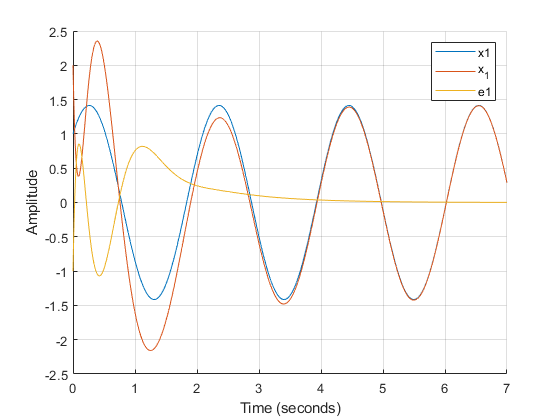

simtime = 7;
simul = sim("model2.slx", simtime);
grid on;
hold on;
plot(simul.x1.Time, simul.x1.Data);
plot(simul.x_1.Time, simul.x_1.Data);
plot(simul.e1.Time, simul.e1.Data);
xlabel('Time (seconds)');
ylabel('Amplitude');
legend('x1', 'x_1', 'e1');

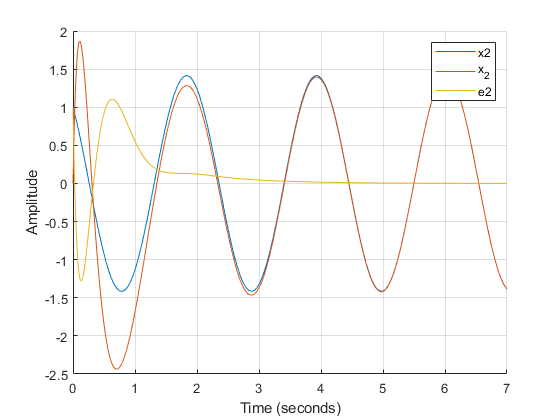


figure;
grid on;
hold on;
plot(simul.x2.Time, simul.x2.Data);
plot(simul.x_2.Time, simul.x_2.Data);
plot(simul.e2.Time, simul.e2.Data);
xlabel('Time (seconds)');
ylabel('Amplitude');
legend('x2', 'x_2', 'e2');

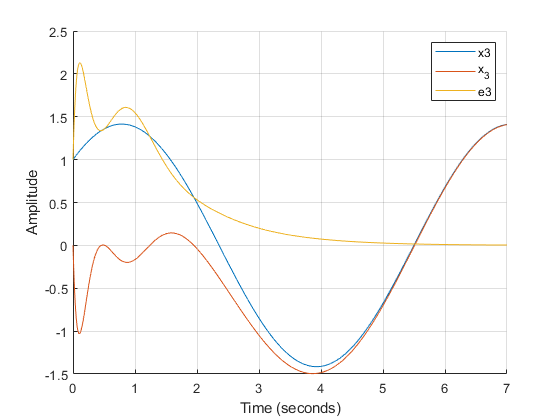

figure;
grid on;
hold on;
plot(simul.x3.Time, simul.x3.Data);
plot(simul.x_3.Time, simul.x_3.Data);
plot(simul.e3.Time, simul.e3.Data);
xlabel('Time (seconds)');
ylabel('Amplitude');
legend('x3', 'x_3', 'e3');

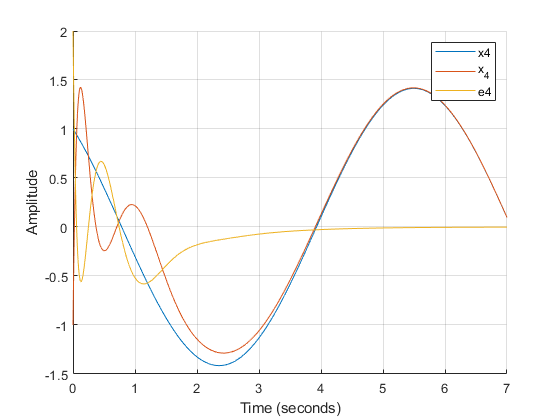


figure;
grid on;
hold on;
plot(simul.x4.Time, simul.x4.Data);
plot(simul.x_4.Time, simul.x_4.Data);
plot(simul.e4.Time, simul.e4.Data);
xlabel('Time (seconds)');
ylabel('Amplitude');
legend('x4', 'x_4', 'e4');